# `智能控制 课程考查`

# `Indirect Model Reference Aapative RBF Control —— `

# `Initial Parameters Optimized by Generic Algthorim `

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.19）

% 这里的控制思想是？ 前馈控制器(NN逼近器)去逼近被控对象的逆 嘛
% 调整了u的位置，方便理解
% 需寻优参数   w->[当前0.1]  cScar->[当前4]   bj->[当前0.5]  采样需1024*32确保结果是稳定的

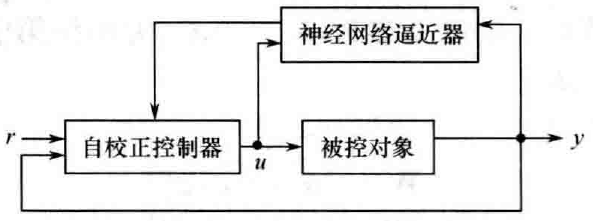

% Self-Correct control based RBF Identification
clear all;
clc;
close all;

SampleN = 1024*48 ; % index
TimeStamp = zeros(1,SampleN); % Specific Time
ts = 0.02;  % 50 Hz
 
neuroN = 12; % Even better
Array = 1:1: neuroN/2;

xite1 =0.001;
alfa  =0.005;

cScar = 1/(neuroN/2)*4;
cij = [-sort(Array,'descend')*cScar  sort(Array)*cScar];
bj =  0.5*ones(neuroN,1) ;        
w = 0.1*ones(neuroN,1);
w_1=w; w_2=w_1; 
;
r = zeros(1,SampleN);
u = zeros(1,SampleN); u_1=0;
y = zeros(1,SampleN); y_1=0; ym = zeros(1,SampleN);
h = zeros(neuroN,1);
g = zeros(1,SampleN);  Ng = zeros(1,SampleN);
e = zeros(1,SampleN);


$$r_k$$


 $y_k =\psi \left(y_{k-1,} \;u_{k-1} \right)\;\;$  具体： ${\;y}_k =g\left\lbrack y_{k-1} \right\rbrack +f\left\lbrack y_{k-1} \right\rbrack \cdot u_{k-1}$


$$N_{g\;k} =\xi \left(y_k ,w_{k-1} \;\right)$$
   


$$N_{f\;k} =\zeta \left(y_k ,v_{k-1} \;\right)$$
    


$$u_k =\Phi \left(N_{g\;k} ,\;N_{f\;k} ,r_k \;\right)$$
  

————————————————

$y_{m\;\;k} =\Theta \left(N_{g\;k} ,\;N_{f\;k} ,\;u_{k-1} \;\right)$  当次预估输出 

$e_k =y_k -y_{m\;\;k}$     最主要是核对error的含义


$$w_k =\Gamma \left(e_k ,{\;w}_{k-1,} {\;\;w}_{k-2} ,\;\alpha ,{\;\eta }_1 \right)$$
 


$$v_k =Z\left(e_k ,{\;v}_{k-1,} {\;\;v}_{k-2} ,\;\alpha ,\;\eta_2 ,{\;u}_{k-1} \;\right)$$
 

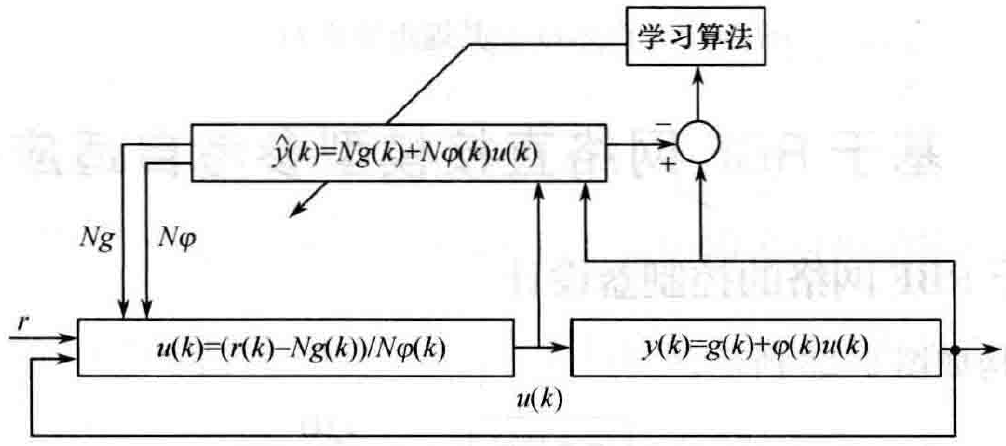

for k=1:1:SampleN
    TimeStamp(k) = k*ts;
   r(k) = sin(2*pi*k*ts/25) + sin(2*pi*k*ts/10);  
    
 %Practical Plant; %  Test for Job9_2
 
    y(k) = 0.8*y_1/(1+y_1^2) + u_1^3;
    g(k) = 0.8*y_1/(1+y_1^2);
     
    for j=1:1:neuroN
        h(j) = exp( -norm(y(k)-cij(:,j))^2 / (2*bj(j)*bj(j)) );
    end
    
    Ng(k) = w_1'*h;

    u(k) = (r(k)-Ng(k))^(1/3) ;
    
    ym(k) = Ng(k) + u_1^3; % hat
 
    %————————————————————   ———————————————————————
    e(k) = y(k)-ym(k);
 
    d_w = 0*w;
    for j=1:1:neuroN
        d_w(j) = xite1 * e(k) * h(j);
    end
    w = w_1 + d_w + alfa*(w_1-w_2);
 
    %———————————————————— Exit Update ———————————————————————
    u_1 =u(k);
    y_1 =y(k);
    w_2=w_1;  w_1=w;
 end

cij

cij =    -4.0000   -3.3333   -2.6667   -2.0000   -1.3333   -0.6667    0.6667    1.3333    2.0000    2.6667    3.3333    4.0000


bj

bj =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


w

w =    0.0998 + 0.0000i
   0.0898 + 0.0000i
  -0.0097 + 0.0001i
  -0.1851 + 0.0005i
  -0.2038 + 0.0019i
  -0.2898 + 0.0066i
   0.2915 + 0.0074i
   0.2014 + 0.0024i
   0.1624 + 0.0006i
   0.1162 + 0.0001i


figure(1);
plot(TimeStamp,r,'r' ,TimeStamp,y,'b:','linewidth',1);

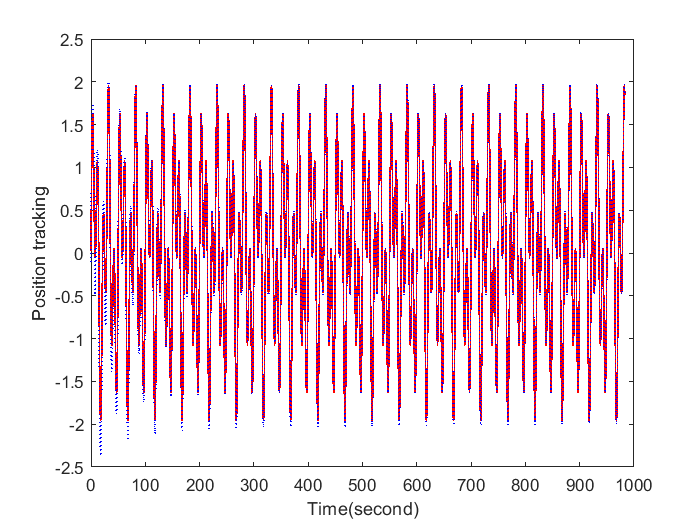

% ,TimeStamp,y,'b:'
xlabel('Time(second)');ylabel('Position tracking');

figure(2);
plot(TimeStamp,e,'r');

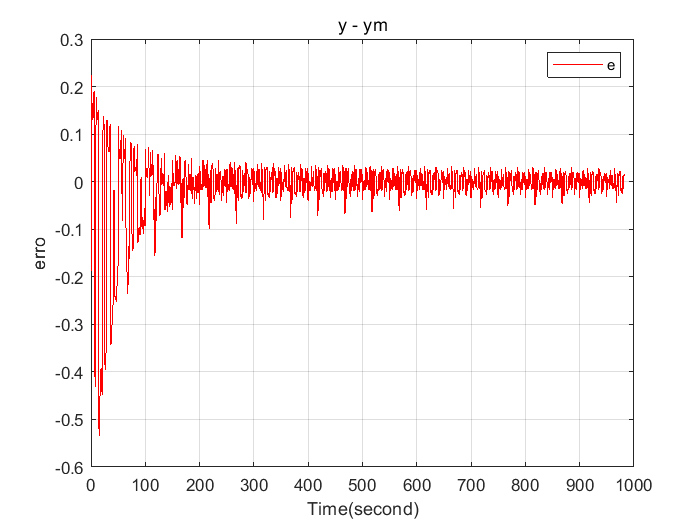

legend('e');
title('y - ym')
xlabel('Time(second)');ylabel('erro');
grid on


figure(3);
plot(TimeStamp,g,'r',TimeStamp,Ng,'b'); % 

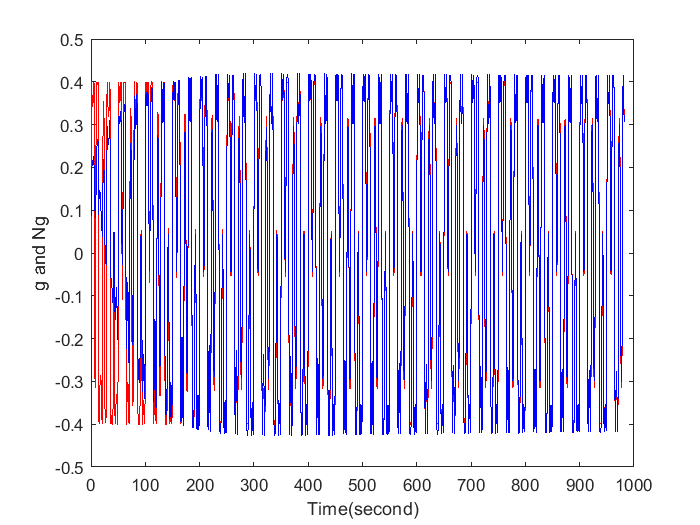

xlabel('Time(second)');ylabel('g and Ng');